# Lab - 7

#### Let f(x) = tan−1(x) and x0 = 0, x1 = 0.2, x2 = 0.4, x3 = 0.6, x4 = 0.8, x5 = 1.0. Calculate the forward differences Δf0, Δ2f0,

#### Δ3f0, Δ4f0, Δ5f0. Write a MATLAB program to compute the forward differences and find the Newton’s forward difference interpolating

#### polynomial P5(x) using these differences at x=0.25.

x = [0,0.2,0.4,0.6,0.8,1.0]

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000


y = f(x)

y =          0    0.1974    0.3805    0.5404    0.6747    0.7854


p0 = 0.25;

step_size = 0.2;

h=step_size; 

length_x = length(x);
n = length_x;
forward_differences = zeros(n,n); 
forward_differences(:,1) = y;

for j = 2:n
    for i = j:n
    forward_differences(i,j) = forward_differences(i,j-1) - forward_differences(i-1,j-1);
    end
end

forward_differences 

forward_differences =          0         0         0         0         0         0
    0.1974    0.1974         0         0         0         0
    0.3805    0.1831   -0.0143         0         0         0
    0.5404    0.1599   -0.0232   -0.0089         0         0
    0.6747    0.1343   -0.0256   -0.0024    0.0065         0
    0.7854    0.1107   -0.0237    0.0019    0.0043   -0.0022


ans = forward_differences(n,n); 

for k=n-1:-1:1 
    P = poly(x(1))/h; 
    P(2) = P(2) - (k-1); 
    ans = conv(ans,P)/k; 
    length_ans=length(ans);
    ans(length_ans) = ans(length_ans) + forward_differences(k,k);
    
end 

coefficients_of_polynomial=ans 

coefficients_of_polynomial =    -0.0572    0.2842   -0.4695    0.0304    0.9975         0


interpolated_value = polyval(ans,p0)

interpolated_value = 0.2450

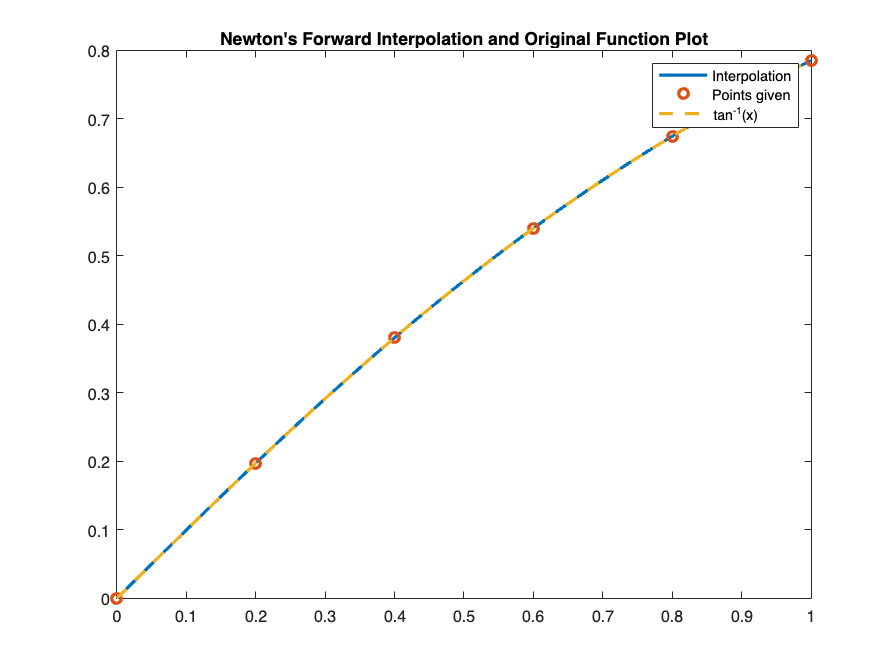


X = linspace(x(1),x(n),100);
Y = polyval(ans,X);

plot(X,Y,LineWidth=2); 

hold on; 

plot(x,y,'o',LineWidth=2); 

plot(X, f(X),'LineStyle','--',LineWidth=2); 

legend('Interpolation','Points given','tan^{-1}(x)');
title('Newton''s Forward Interpolation and Original Function Plot');

hold off; 

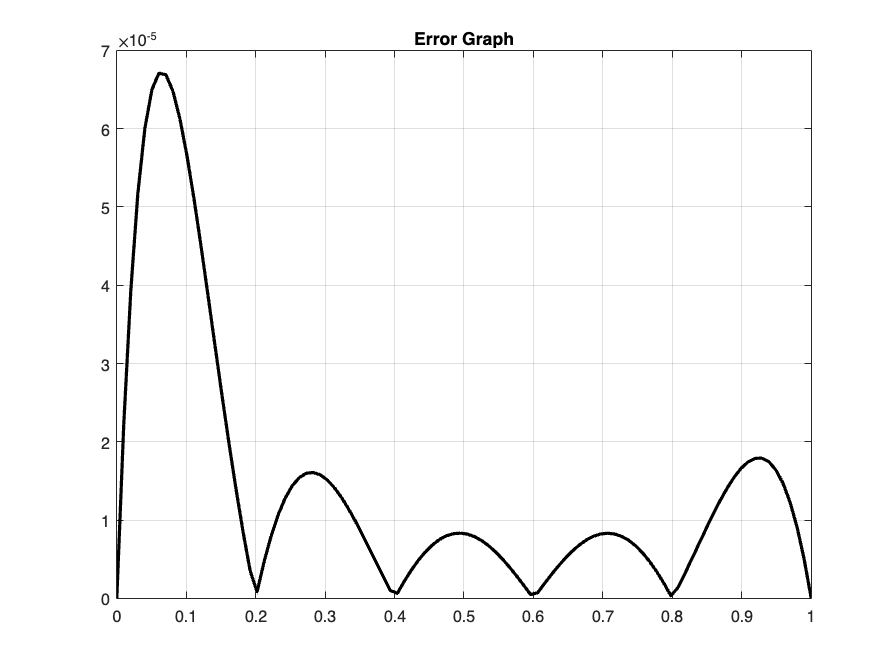


plot(X,abs(Y-f(X)),LineWidth=2,Color=[0 0 0]);
title('Error Graph');
grid on ;

function ret_val = f(passed_value)
    ret_val = atan(passed_value); 
end